# lora sim script

## lora parameters

%clear;
SF=12; %spreading factor 7-12
Fs=125e3;%samplingrate = BW
SPS=2^SF;%samples per symbol



## sim parameters

%data
numSym=round(10000/SF);
randomData=true;
%channel
perfectChannel=false;%no doppler or awgn
maxDopplerShift=0;
flatDoppler=true;%true: apply same shift to entire signal, false: gradient from +maxShift to -maxShift over length of signal
maxSNR=20; %signal to noise ratio in dB
%loops
nLoops=10;
loopSNR=true;
SNRstepsize=2;
loopDoppler=false;

plotSpectrogram=true;

## tx

%generate data
dataLength=numSym*SF;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    messageBits=ones(dataLength,1);
end
%generate lora signal
loraSignal=generateLoraSignal(messageBits,SF,numSym);

decimalSymbols =         2370        3910         102        3203         562        3581        3449        3163        4015        3453         140        3927        2510        3531        1763         729         803         673        1905        4034        3481        2476         425         302        2600         698        2441        1162        2521        3742         103        1005        2617          58           3          58        3477         466        2192        3624         423        2521         575        1368        1230        1838        1209        3011        3070          98


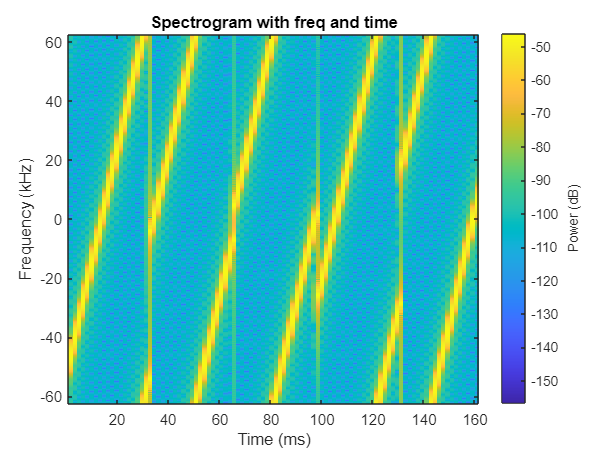

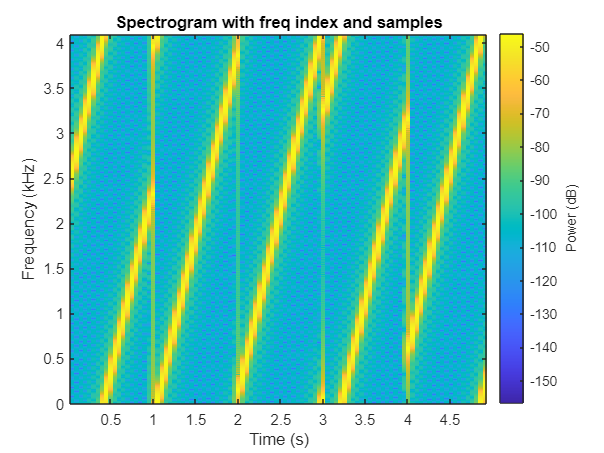


if plotSpectrogram
    %spectroram of first 5 symbols
    figure
    windowLength=round((SPS)/10);
    spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
    title('Spectrogram with freq and time')
    figure
    spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
    title('Spectrogram with freq index and samples')
end

## channel & rx

%channel
for counter=1:nLoops
    if perfectChannel
       rxSignal=loraSignal;
    else
        if loopSNR
            rxSignal=(awgn(loraSignal,maxSNR-(counter-1)*SNRstepsize));
        else
            rxSignal=(awgn(loraSignal,maxSNR));
        end
        %snr
     end
    %rx
    decodedBits=demodulateLoraSignal(rxSignal,SF,numSym);
    errors(counter)=sum(messageBits~=decodedBits);
end

## ber


% lora_ber7=errors/dataLength
% lora_ber9=errors/dataLength
lora_ber12=errors/dataLength

lora_ber12 =          0         0         0    0.0038    0.0374    0.1824    0.3563    0.4408    0.4844    0.4917


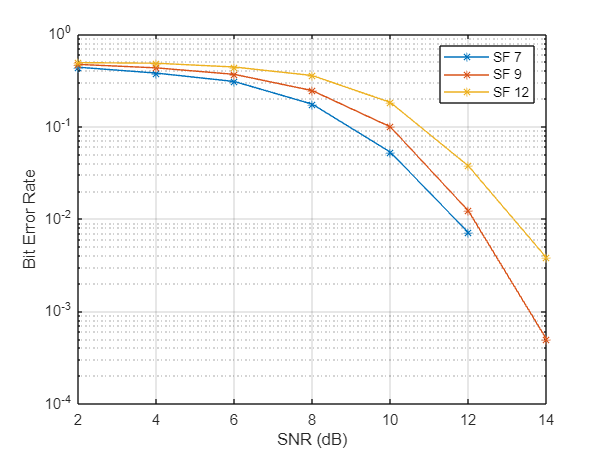

if loopSNR
    figure
    
    SNRvec=flip((maxSNR-(nLoops-1)*SNRstepsize):SNRstepsize:maxSNR);
    semilogy(SNRvec',lora_ber7,'-*')
    hold on
    semilogy(SNRvec',lora_ber9,'-*')
    semilogy(SNRvec',lora_ber12,'-*')
    grid on
    xlabel('SNR (dB)')
    ylabel('Bit Error Rate')
    legend('SF 7','SF 9','SF 12')
    
end